# Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

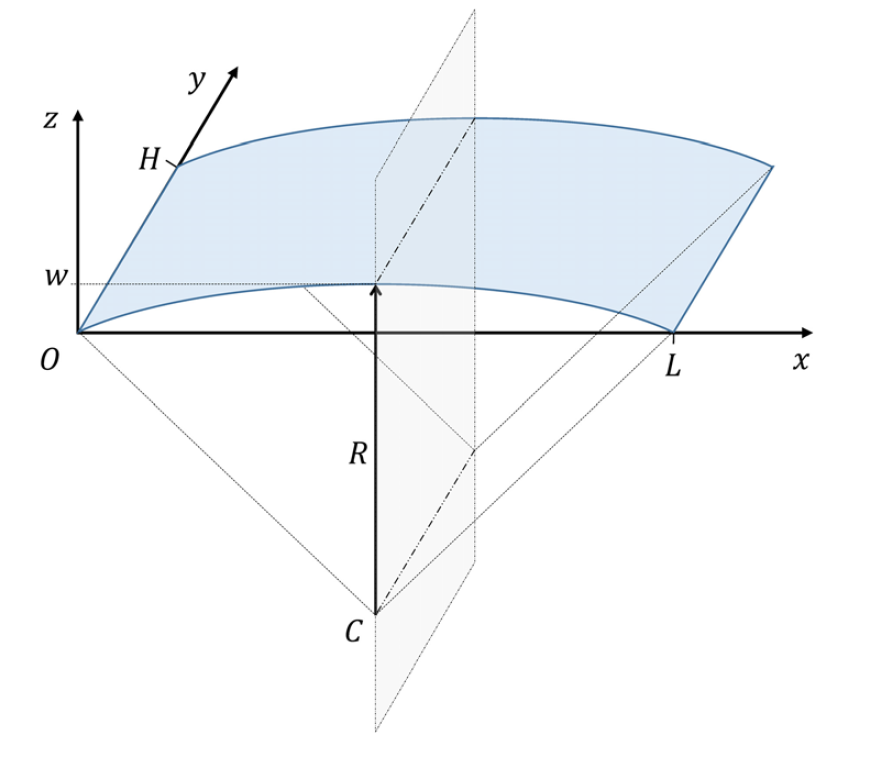

**system parameters**


nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)
epsilon = 0.1;

## generate model

Building FE model


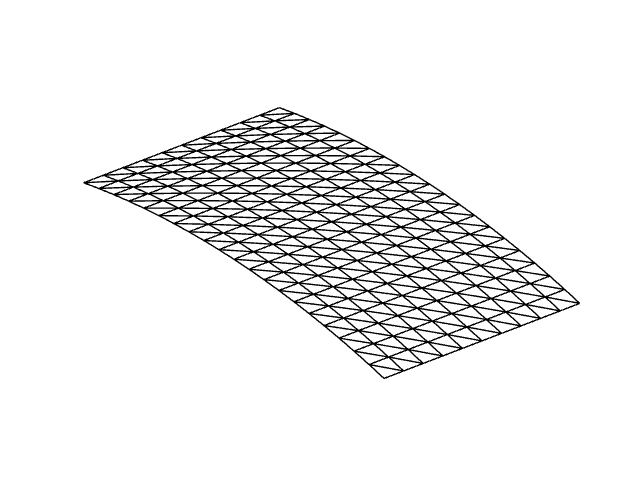

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  显示 所有属性


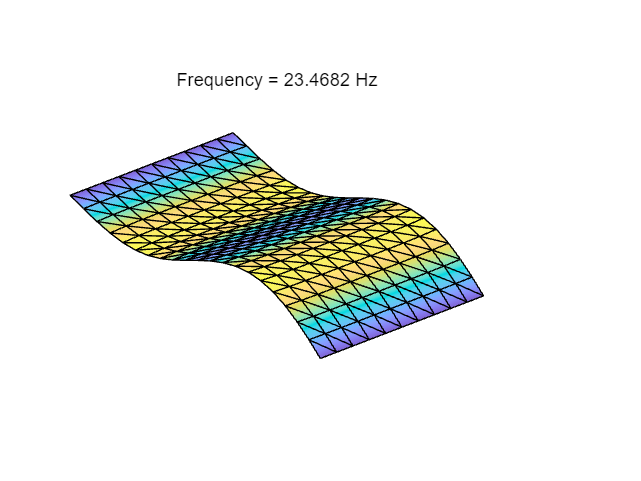

Using Rayleigh damping
Assembling external force vector
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:12


[M,C,K,fnl,f_0,outdof] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',20,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

We assume that there is no external excitation but control inputs

Bext     = zeros(n,2); Bext(outdof(1),1)=1; Bext(outdof(2),2)=1; 
epsilon  = 0.1;
set(DS,'D',Bext,'epsilon',epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 10 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.269789e-03
modal damping ratio for 4 mode is 2.721500e-03
modal damping ratio for 5 mode is 2.909530e-03
modal damping ratio for 6 mode is 3.773001e-03
modal damping ratio for 7 mode is 3.967986e-03
modal damping ratio for 8 mode is 4.154750e-03
modal damping ratio for 9 mode is 4.434185e-03
modal damping ratio for 10 mode is 4.442169e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 20 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4745i
  -0.0029 - 1.4745i
  -0.0063 + 3.1598i
  -0.0063 - 3.1598i
  -0.0094 + 4.1319i
  -0.0094 - 4.1319i
  -0.0148 + 5.4515i
  -0.0148 - 5.4515i
  -0.0173 +

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     4     0
     5     1
     6     2
     7     3
     0     4
     1     5
     2     6
     3     7

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0173 + 5.9601i
  -0.0173 + 5.9601i
  -0.0173 + 5.9601i
  -0.0173 + 5.9601i
  -0.0173 - 5.9601i
  -0.0173 - 5.9601i
  -0.0173 - 5.9601i
  -0.0173 - 5.9601i

sigma_out = 14
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0029 + 1.4745i
  -0.0029 + 1.4745i
  -0.0029 + 1.4745i
  -0.0029 + 1.4745i
  -0.0029 - 1.4745i
  -0.0029 - 1.4745i
  -0.0029 - 1.4745i
  -0.0029 - 1.4745i

sigma_in = 14


order = 5;
% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.27E+01 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.37E+01 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.48E+01 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.67E+01 MB


% om = 2*pi/2;
% nsteps = 200;
% deflec = load('load300.mat');
% DSstatic = DynamicalSystem();
% set(DSstatic,'M',M,'C',1000*C,'K',K,'fnl',fnl);
% set(DSstatic.Options,'HarmonicForce',false);
% fmidspan = zeros(n,1);
% fmidspan(outdof(1)) = 4000;
% Fmidspan = @(t) fmidspan;
% set(DSstatic,'fext',Fmidspan);
% [ts, xs, xf] = time_integration_transient(DSstatic,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','Newmark','outdof',outdof,'init',deflec.z0);
% figure;
% plot(ts,xs(:,1))
% % construct initial condition
% z0 = xf';
z0 = load('load400.mat','z0'); z0 = z0.z0;

### Stablization via LQR control

auData = construct_autoData(DS, masterModes, R_0);
tf     = 0.6; nsteps = 3000;
tspan  = linspace(0,tf,nsteps);
cont   = struct();
cont.Q    = 1e4*eye(2*n);
cont.Rhat = 0.1*eye(2);
cont.Mhat = 0e1*eye(2*n); 
cont.Qf=1e4*eye(2*n)

cont = 包含以下字段的 struct :
       Q: [2640×2640 double]
    Rhat: [2×2 double]
    Mhat: [2640×2640 double]
      Qf: [2640×2640 double]


set(DS.Options, 'outDOF', outdof);

**ROM-based closed loop control**

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 5.501318e-01 
Time for backward simulation of Riccati ODE is 1.030938e-01
Time for backward simulation of compensated ODE is 7.416396e-01
Time for forward simulation of ODEs for modal coordinates is 8.568663e-01
Plot relative invariance error


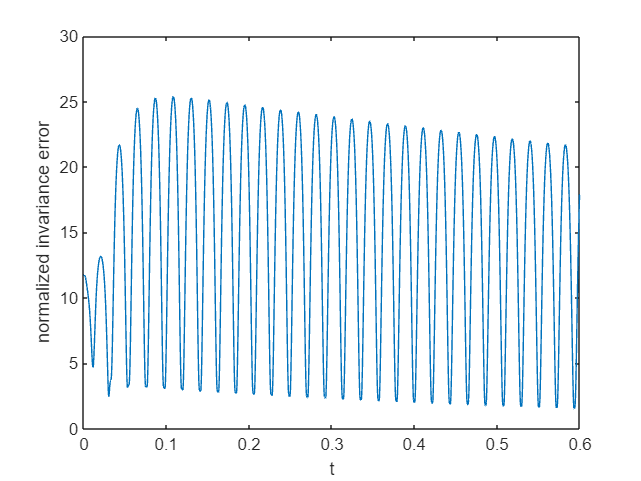

traj_closed = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W_0,masterModes,1:2,cont);

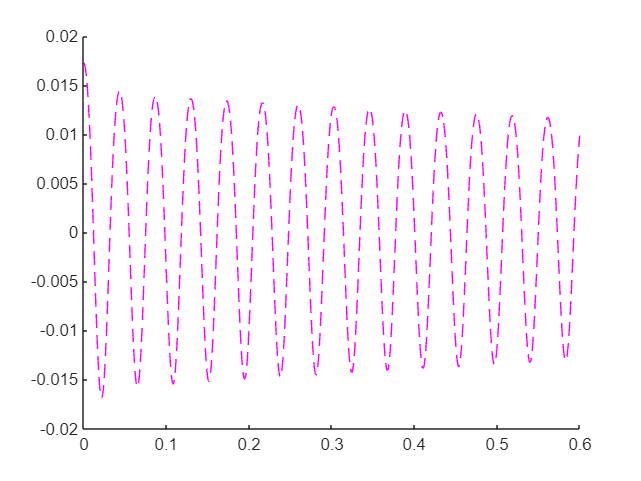

figure; hold on
plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');

**Full dynamics simulation - without control**

om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99965
Iteration 1, Residual norm = 0.0052428
Iteration 2, Residual norm = 2.3243e-08
time integration completed: 0.033333%
Iteration 0, Residual norm = 0.99909
Iteration 1, Residual norm = 0.0065427
Iteration 2, Residual norm = 2.4684e-08
time integration completed: 0.066667%
Iteration 0, Residual norm = 0.99937
Iteration 1, Residual norm = 0.004156
Iteration 2, Residual norm = 9.6993e-09
time integration completed: 0.1%
Iteration 0, Residual norm = 0.99916
Iteration 1, Residual norm = 0.004109
Iteration 2, Residual norm = 8.2053e-10
time integration completed: 0.13333%
Iteration 0, Residual norm = 0.99893
Iteration 1, Residual norm = 0.0028095
Iteration 2, Residual norm = 2.4013e-10
time integration completed: 0.16667%
Iteration 0, Residual norm = 0.99825
Iteration 1, Residual norm = 0.0024171
Iteration 2, Residual norm = 2.6856e-10
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99771
Iteration 1, Residual norm = 0.0026934
Iteration 2, R

**Full dynamics simulation - with control**

ufun = @(t) transpose(interp1(traj_closed.time,traj_closed.ut',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99936
Iteration 1, Residual norm = 0.005244
Iteration 2, Residual norm = 2.3509e-08
time integration completed: 0.033333%
Iteration 0, Residual norm = 0.99903
Iteration 1, Residual norm = 0.0065612
Iteration 2, Residual norm = 2.4921e-08
time integration completed: 0.066667%
Iteration 0, Residual norm = 0.99924
Iteration 1, Residual norm = 0.0041679
Iteration 2, Residual norm = 9.7866e-09
time integration completed: 0.1%
Iteration 0, Residual norm = 0.99879
Iteration 1, Residual norm = 0.0041208
Iteration 2, Residual norm = 8.2915e-10
time integration completed: 0.13333%
Iteration 0, Residual norm = 0.99824
Iteration 1, Residual norm = 0.0028141
Iteration 2, Residual norm = 2.4235e-10
time integration completed: 0.16667%
Iteration 0, Residual norm = 0.99724
Iteration 1, Residual norm = 0.0024103
Iteration 2, Residual norm = 2.6985e-10
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99605
Iteration 1, Residual norm = 0.0026755
Iteration 2, 

### Comparison with full dynamics

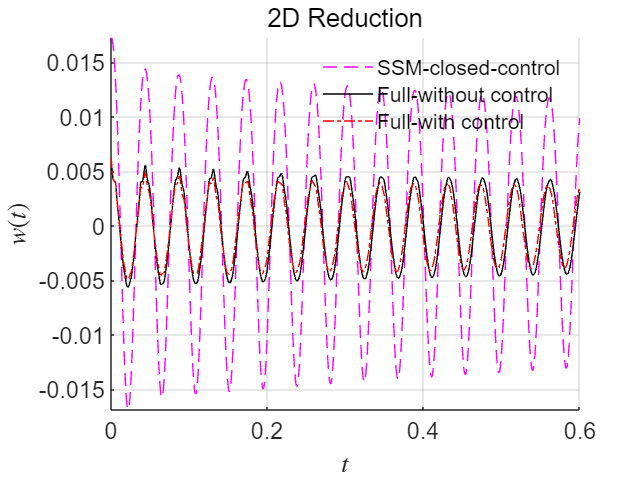

figure; hold on
plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control');
plot(tfullwc, xfullwc(:,1),'r-.','DisplayName', 'Full-with control');
legend('show'); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w(t)$');
ylabel(zk,'Interpreter','latex');
title('2D Reduction')
set(gca,'FontSize',14);
grid on, axis tight

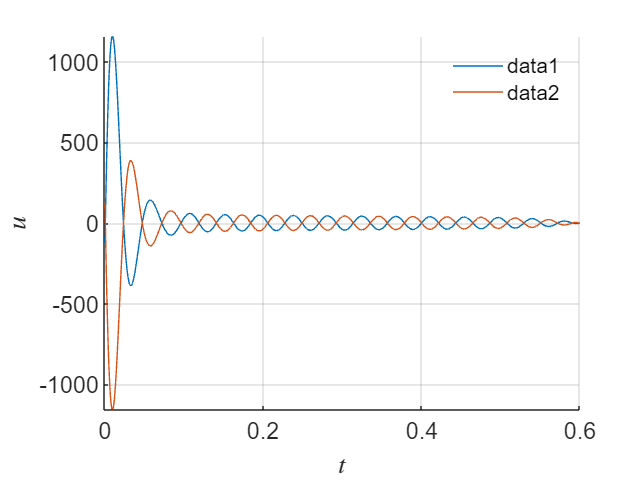

figure; hold on;
plot(traj_closed.time,traj_closed.ut);
xlabel('$t$','Interpreter',"latex")
ylabel('$u$','Interpreter','latex')
legend('show'); legend boxoff
set(gca,'FontSize',14); grid on, axis tight

Next we try the implementation of two segments

## Moving window

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 3.271740e-02 
Time for backward simulation of Riccati ODE is 4.797140e-02
Time for backward simulation of compensated ODE is 4.806903e-01
Time for forward simulation of ODEs for modal coordinates is 5.290492e-01
Plot relative invariance error


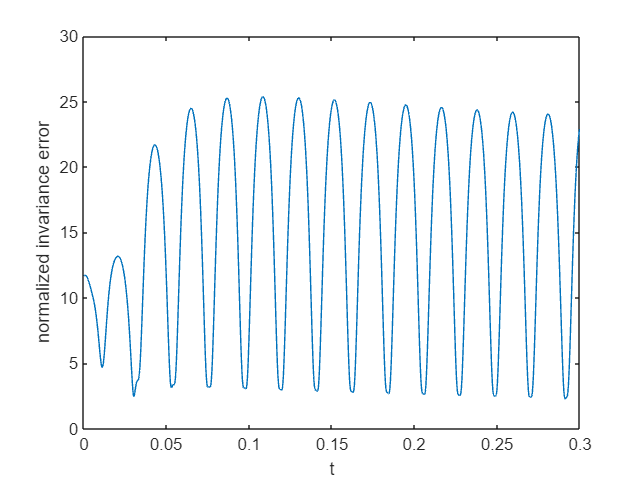

Iteration 0, Residual norm = 0.99936
Iteration 1, Residual norm = 0.005244
Iteration 2, Residual norm = 2.3509e-08
time integration completed: 0.066667%
Iteration 0, Residual norm = 0.99903
Iteration 1, Residual norm = 0.0065612
Iteration 2, Residual norm = 2.4921e-08
time integration completed: 0.13333%
Iteration 0, Residual norm = 0.99924
Iteration 1, Residual norm = 0.0041679
Iteration 2, Residual norm = 9.7866e-09
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99878
Iteration 1, Residual norm = 0.0041208
Iteration 2, Residual norm = 8.2915e-10
time integration completed: 0.26667%
Iteration 0, Residual norm = 0.99824
Iteration 1, Residual norm = 0.0028141
Iteration 2, Residual norm = 2.4238e-10
time integration completed: 0.33333%
Iteration 0, Residual norm = 0.99724
Iteration 1, Residual norm = 0.0024103
Iteration 2, Residual norm = 2.6982e-10
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99605
Iteration 1, Residual norm = 0.0026755
Iteration 2, R

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 2.082260e-02 
Time for backward simulation of Riccati ODE is 3.236270e-02
Time for backward simulation of compensated ODE is 3.828440e-01
Time for forward simulation of ODEs for modal coordinates is 3.989511e-01
Plot relative invariance error


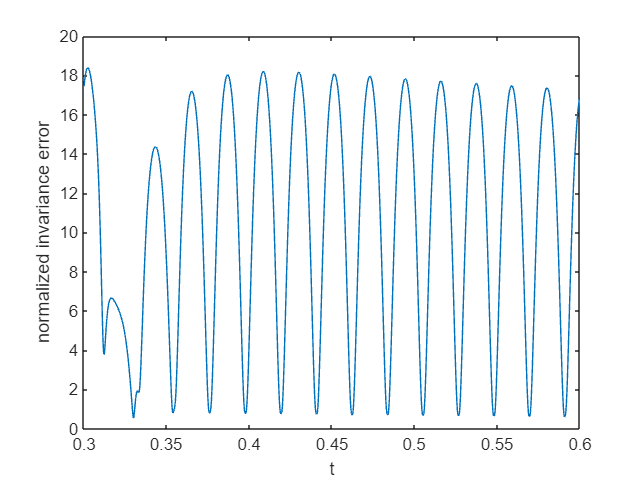

Iteration 0, Residual norm = 0.90764
Iteration 1, Residual norm = 1.4181e-05
Iteration 2, Residual norm = 4.0434e-12
time integration completed: 50.0333%
Iteration 0, Residual norm = 0.93416
Iteration 1, Residual norm = 1.5775e-05
Iteration 2, Residual norm = 4.1257e-12
time integration completed: 50.0667%
Iteration 0, Residual norm = 0.93709
Iteration 1, Residual norm = 2.1265e-05
Iteration 2, Residual norm = 4.1841e-12
time integration completed: 50.1%
Iteration 0, Residual norm = 0.94598
Iteration 1, Residual norm = 2.1149e-05
Iteration 2, Residual norm = 3.8243e-12
time integration completed: 50.1333%
Iteration 0, Residual norm = 0.95505
Iteration 1, Residual norm = 2.5196e-05
Iteration 2, Residual norm = 4.1111e-12
time integration completed: 50.1667%
Iteration 0, Residual norm = 0.96254
Iteration 1, Residual norm = 3.0979e-05
Iteration 2, Residual norm = 3.9229e-12
time integration completed: 50.2%
Iteration 0, Residual norm = 0.97509
Iteration 1, Residual norm = 3.4093e-05
Itera

ts = [0 0.3 0.6]; nsteps = 1500 ;
nint = numel(ts)-1;
xf = z0;
trajs = cell(nint,1); tfullc = cell(nint,1); xfullc = cell(nint,1);
% the number of linear modes is very important - to follow
for k=1:nint
    ta = ts(k); tb = ts(k+1);
    tspan = linspace(ta,tb,nsteps);
    traj   = LQR_closed_loop(DS,xf,'nonlinear',tspan,auData,W_0,masterModes,1:2,cont);
    ufun  = @(t) transpose(interp1(traj.time,traj.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
    [tk, xk, xkf] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
        1, 'nSteps', nsteps,...
        'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',ta);%%%%%%%%%
    % update initial condition
    xf = xkf';
    % record results
    trajs{k}  = traj;
    tfullc{k} = tk;
    xfullc{k} = xk;
end

### Comparison with full dynamics

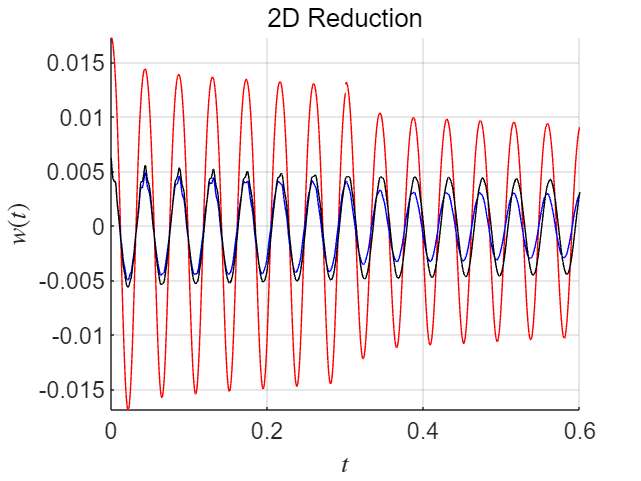

figure; hold on
for k=1:nint
    plot(trajs{k}.time, trajs{k}.zt(1,:),'r-');
    plot(tfullc{k}, xfullc{k}(:,1),'b-');
end
plot(tfullwo, xfullwo(:,1),'k-');
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w(t)$');
ylabel(zk,'Interpreter','latex');
title('2D Reduction')
set(gca,'FontSize',14);
grid on, axis tight

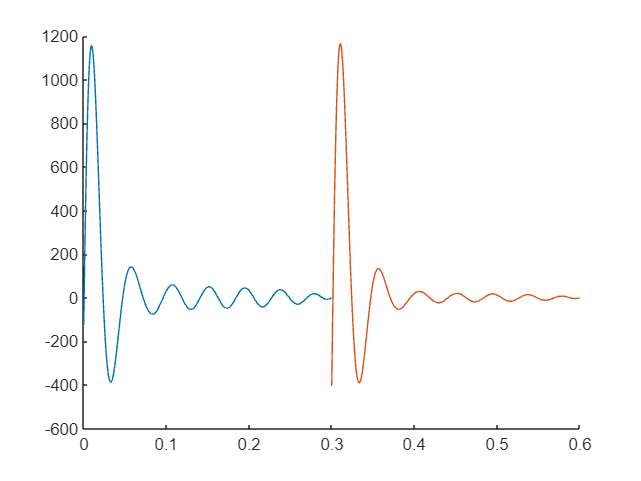

figure; hold on
for k=1:nint
    plot(trajs{k}.time, trajs{k}.ut(1,:),'DisplayName','SSM-control');
end

## On the number of linear modes

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 2.028240e-02 
Time for backward simulation of Riccati ODE is 3.976555e-01
Time for backward simulation of compensated ODE is 1.964418e+00
Time for forward simulation of ODEs for modal coordinates is 8.540618e-01
Plot relative invariance error


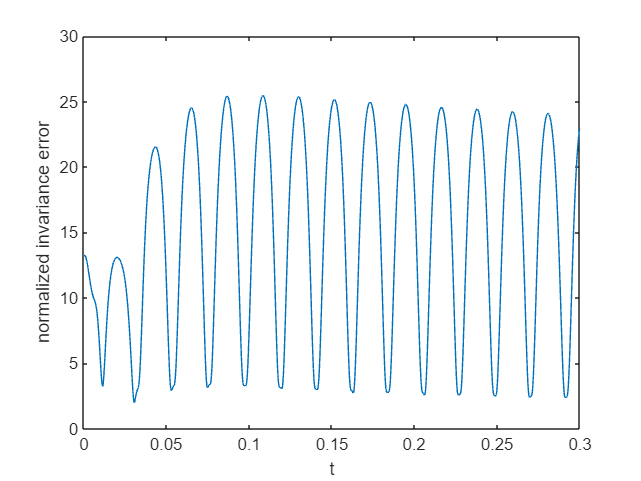

Iteration 0, Residual norm = 0.99936
Iteration 1, Residual norm = 0.0052403
Iteration 2, Residual norm = 2.358e-08
time integration completed: 0.066667%
Iteration 0, Residual norm = 0.99884
Iteration 1, Residual norm = 0.0065594
Iteration 2, Residual norm = 2.4928e-08
time integration completed: 0.13333%
Iteration 0, Residual norm = 0.99897
Iteration 1, Residual norm = 0.0041602
Iteration 2, Residual norm = 9.7682e-09
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99846
Iteration 1, Residual norm = 0.0041187
Iteration 2, Residual norm = 8.2982e-10
time integration completed: 0.26667%
Iteration 0, Residual norm = 0.99783
Iteration 1, Residual norm = 0.0028131
Iteration 2, Residual norm = 2.4246e-10
time integration completed: 0.33333%
Iteration 0, Residual norm = 0.99679
Iteration 1, Residual norm = 0.0024049
Iteration 2, Residual norm = 2.6935e-10
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99532
Iteration 1, Residual norm = 0.0026633
Iteration 2, R

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 3.337460e-02 
Time for backward simulation of Riccati ODE is 3.570133e-01
Time for backward simulation of compensated ODE is 1.858440e+00
Time for forward simulation of ODEs for modal coordinates is 7.974442e-01
Plot relative invariance error


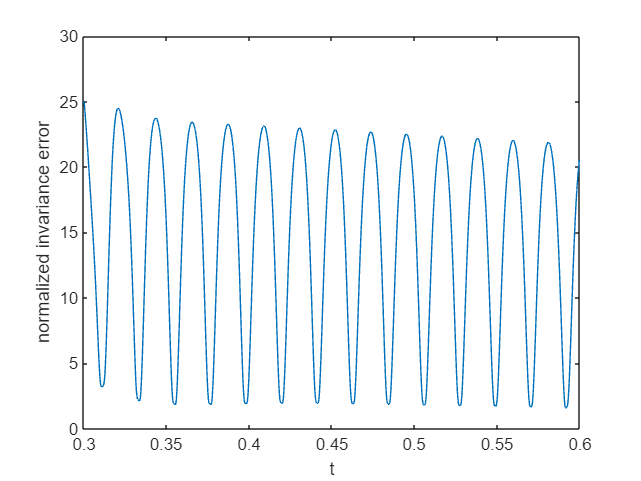

Iteration 0, Residual norm = 0.88968
Iteration 1, Residual norm = 2.5955e-05
Iteration 2, Residual norm = 3.6156e-12
time integration completed: 50.0333%
Iteration 0, Residual norm = 0.90839
Iteration 1, Residual norm = 2.6012e-05
Iteration 2, Residual norm = 3.5188e-12
time integration completed: 50.0667%
Iteration 0, Residual norm = 0.8932
Iteration 1, Residual norm = 3.319e-05
Iteration 2, Residual norm = 3.6884e-12
time integration completed: 50.1%
Iteration 0, Residual norm = 0.8855
Iteration 1, Residual norm = 2.8126e-05
Iteration 2, Residual norm = 3.5266e-12
time integration completed: 50.1333%
Iteration 0, Residual norm = 0.87648
Iteration 1, Residual norm = 3.3555e-05
Iteration 2, Residual norm = 3.614e-12
time integration completed: 50.1667%
Iteration 0, Residual norm = 0.85235
Iteration 1, Residual norm = 3.8553e-05
Iteration 2, Residual norm = 3.698e-12
time integration completed: 50.2%
Iteration 0, Residual norm = 0.85279
Iteration 1, Residual norm = 4.4435e-05
Iteration 

xf = z0;
trajs2 = cell(nint,1); tfullc2 = cell(nint,1); xfullc2 = cell(nint,1);
% the number of linear modes is very important - to follow
for k=1:nint
    ta = ts(k); tb = ts(k+1);
    tspan = linspace(ta,tb,nsteps);
    traj   = LQR_closed_loop(DS,xf,'nonlinear',tspan,auData,W_0,masterModes,1:10,cont);
    ufun  = @(t) transpose(interp1(traj.time,traj.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
    [tk, xk, xkf] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
        1, 'nSteps', nsteps,...
        'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',ta);
    % update initial condition
    xf = xkf';
    % record results
    trajs2{k}  = traj;
    tfullc2{k} = tk;
    xfullc2{k} = xk;
end

### Comparison with full dynamics

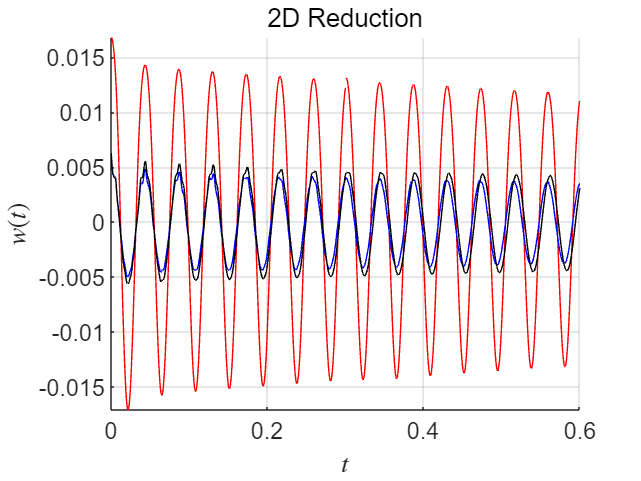

figure; hold on
for k=1:nint
    plot(trajs2{k}.time, trajs2{k}.zt(1,:),'r-');
    plot(tfullc2{k}, xfullc2{k}(:,1),'b-');
end
plot(tfullwo, xfullwo(:,1),'k-');
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w(t)$');
ylabel(zk,'Interpreter','latex');
title('2D Reduction')
set(gca,'FontSize',14);
grid on, axis tight

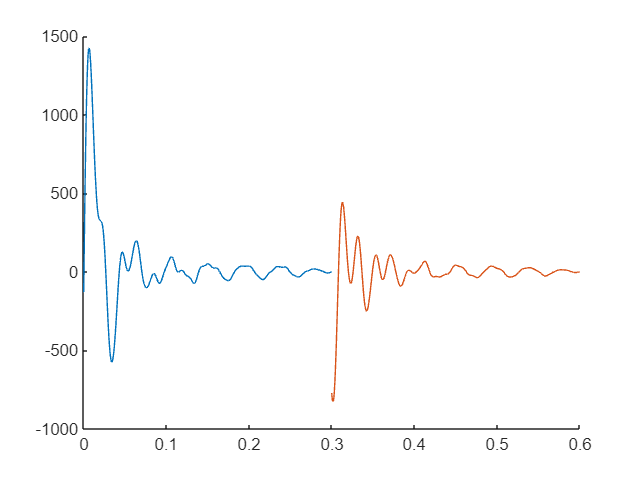

figure; hold on
for k=1:nint
    plot(trajs2{k}.time, trajs2{k}.ut(1,:),'DisplayName','SSM-control');
end

## On the number of linear modes

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 1.055390e-02 
Time for backward simulation of Riccati ODE is 4.884543e+00
Time for backward simulation of compensated ODE is 5.818135e+00
Time for forward simulation of ODEs for modal coordinates is 3.139861e+00
Plot relative invariance error


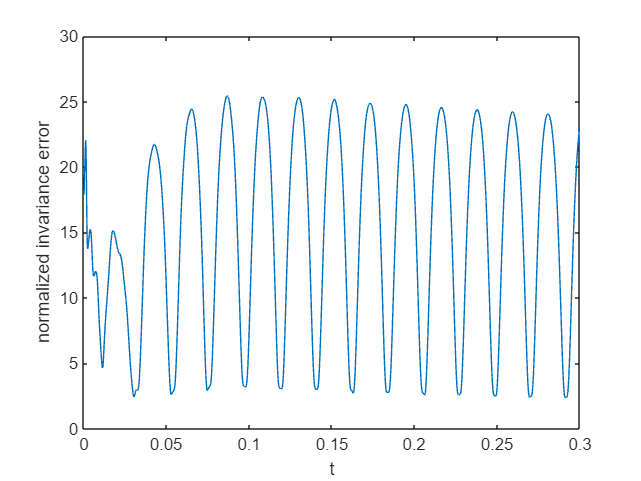

Iteration 0, Residual norm = 0.99784
Iteration 1, Residual norm = 0.0050652
Iteration 2, Residual norm = 2.6661e-08
time integration completed: 0.066667%
Iteration 0, Residual norm = 0.9919
Iteration 1, Residual norm = 0.0065057
Iteration 2, Residual norm = 2.5491e-08
time integration completed: 0.13333%
Iteration 0, Residual norm = 0.98895
Iteration 1, Residual norm = 0.0038779
Iteration 2, Residual norm = 9.3368e-09
time integration completed: 0.2%
Iteration 0, Residual norm = 0.98397
Iteration 1, Residual norm = 0.0039171
Iteration 2, Residual norm = 8.1475e-10
time integration completed: 0.26667%
Iteration 0, Residual norm = 0.97824
Iteration 1, Residual norm = 0.0026717
Iteration 2, Residual norm = 2.214e-10
time integration completed: 0.33333%
Iteration 0, Residual norm = 0.97416
Iteration 1, Residual norm = 0.0020973
Iteration 2, Residual norm = 2.1467e-10
time integration completed: 0.4%
Iteration 0, Residual norm = 0.9634
Iteration 1, Residual norm = 0.002173
Iteration 2, Resi

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 4.490700e-03 
Time for backward simulation of Riccati ODE is 4.883145e+00
Time for backward simulation of compensated ODE is 5.593914e+00
Time for forward simulation of ODEs for modal coordinates is 3.244650e+00
Plot relative invariance error


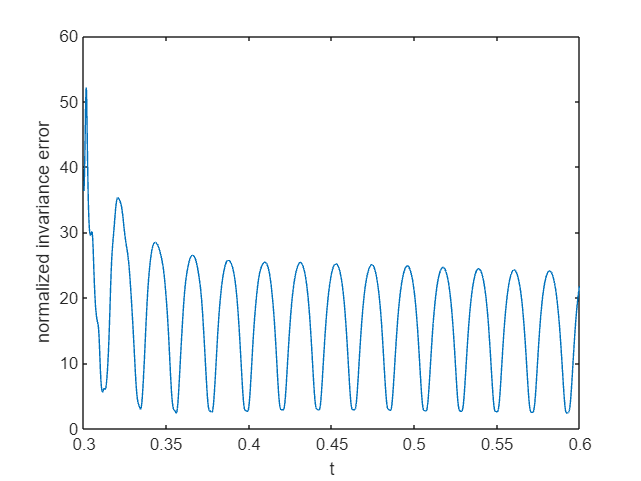

Iteration 0, Residual norm = 0.90229
Iteration 1, Residual norm = 6.4432e-05
Iteration 2, Residual norm = 3.6701e-12
time integration completed: 50.0333%
Iteration 0, Residual norm = 0.89771
Iteration 1, Residual norm = 4.2273e-05
Iteration 2, Residual norm = 3.4359e-12
time integration completed: 50.0667%
Iteration 0, Residual norm = 0.85918
Iteration 1, Residual norm = 3.4321e-05
Iteration 2, Residual norm = 3.3308e-12
time integration completed: 50.1%
Iteration 0, Residual norm = 0.81437
Iteration 1, Residual norm = 2.8225e-05
Iteration 2, Residual norm = 2.8515e-12
time integration completed: 50.1333%
Iteration 0, Residual norm = 0.76614
Iteration 1, Residual norm = 2.4911e-05
Iteration 2, Residual norm = 2.8076e-12
time integration completed: 50.1667%
Iteration 0, Residual norm = 0.71428
Iteration 1, Residual norm = 2.4664e-05
Iteration 2, Residual norm = 2.5439e-12
time integration completed: 50.2%
Iteration 0, Residual norm = 0.66502
Iteration 1, Residual norm = 2.4882e-05
Itera

xf = z0;
trajs3 = cell(nint,1); tfullc3 = cell(nint,1); xfullc3 = cell(nint,1);
% the number of linear modes is very important - to follow
for k=1:nint
    ta = ts(k); tb = ts(k+1);
    tspan = linspace(ta,tb,nsteps);
    traj   = LQR_closed_loop(DS,xf,'nonlinear',tspan,auData,W_0,masterModes,1:20,cont);
    ufun  = @(t) transpose(interp1(traj.time,traj.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
    [tk, xk, xkf] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
        1, 'nSteps', nsteps,...
        'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',ta);
    % update initial condition
    xf = xkf';
    % record results
    trajs3{k}  = traj;
    tfullc3{k} = tk;
    xfullc3{k} = xk;
end

### Comparison with full dynamics

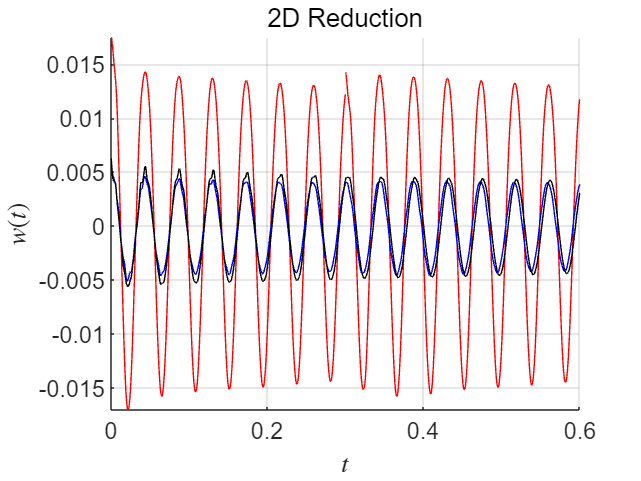

figure; hold on
for k=1:nint
    plot(trajs3{k}.time, trajs3{k}.zt(1,:),'r-');
    plot(tfullc3{k}, xfullc3{k}(:,1),'b-');
end
plot(tfullwo, xfullwo(:,1),'k-');
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w(t)$');
ylabel(zk,'Interpreter','latex');
title('2D Reduction')
set(gca,'FontSize',14);
grid on, axis tight

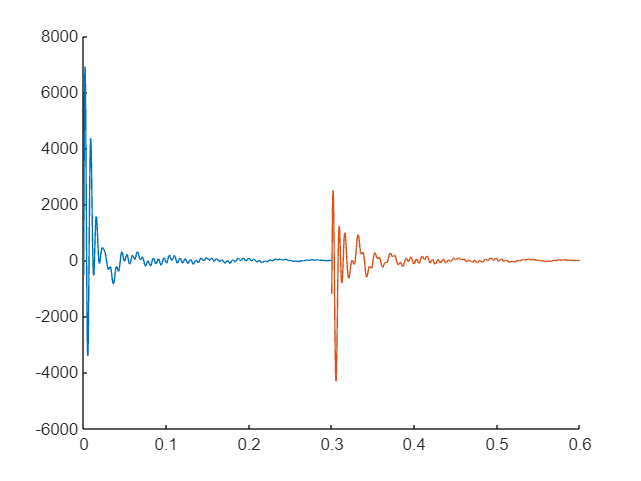

figure; hold on
for k=1:nint
    plot(trajs3{k}.time, trajs3{k}.ut(1,:),'DisplayName','SSM-control');
end

% close all 
% 
% save('zt.mat','trajs3')
% urand=rand(2000, 2, 499);
% 
% tcdim=400;
% X=trajs3{1}.zt(1:tcdim,:)-trajs3{1}.zauto(1:tcdim,:);
% %X=trajs3{1}.zt(1:tcdim,:);
% u=0.1*trajs3{1}.ut(:,1:end-1);
% 
% N=size(X,2)-1;
% timei=linspace(1,N,N);
% 
% 
% 
% 
% X1 = X(:,1:end-1); 
% X2 = X(:,2:end);
% Gama=u(:,1:end);
% Omega=[X1;Gama];
% 
% [U,S,V] = svd(Omega,'econ');
% p=402;
% Utilde = U(:,1:p); 
% Stilde = S(1:p,1:p);
% Vtilde = V(:,1:p);
% 
% U1tilde=Utilde(1:size(X1,1),:);
% U2tilde=Utilde(size(X1,1)+1:size(Utilde,1), :);
% 
% A_=X2*Vtilde*pinv(Stilde)*(U1tilde.')
% B_=X2*Vtilde*pinv(Stilde)*(U2tilde.')%3.17
% 
% [Uup,Sup,Vup]=svd(X2,'econ');
% r=10;
%  Uuptd = Uup(:,1:r); 
%  Suptd = Sup(1:r,1:r);
%  Vuptd = Vup(:,1:r);
% 
% Atilde=(Uuptd.')*A_*Uuptd%3.18
% Btilde=(Uuptd.')*B_
% eig(Atilde)
% 
% [W,eigs] = eig(Atilde);
% phi=X2*Vtilde*inv(Stilde)*(U1tilde.')*Uuptd*W; %3.21
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% Atd=A_;
% Btd=B_;
% Ctd=C;
% Atrk=Atilde;
% Btrk=Btilde;
% Ctrk=C;
% 
% xt=zeros(400,N);
% yt=zeros(1,N);
% ut=zeros(2,N);
% 
% epsino=zeros(r,N);
% ytrk=zeros(1,N);
% utrk=zeros(2,N);
% 
% xt(:,1)=X(1:400,1);
% epsino(:,1)=pinv(Uuptd)*X(1:tcdim,1);
% for k =1:N
%     ut(:,k)=u(:,k);
%     xt(:,k+1)=Atd*xt(:,k)+Btd*ut(:,k);
%     yt(:,k)=xt(1,k);
%     utrk(:,k)=u(:,k);
%     epsino(:,k+1)=Atrk*epsino(:,k)+Btrk*ut(:,k);
% 
% end
% xtrkre=Uuptd*epsino;
% ytrkre=xtrkre(1,1:499);
% 
% y=X2(1,:);
% 
% figure(1);
% plot(timei,y,'b','DisplayName','origin','Color',[0,0,1]);
% hold on;
% figure(1);
% plot(timei,yt,'o','DisplayName','DMD','Color',[1,0,0]);
% plot(timei,ytrkre,'b','DisplayName','origin','Color',[0,1,1]);
% 
% %plot(timei,y,timei,yt)
% 
% 
% 
% 


tcdim=300;
datalength=330;
datastart=1;
p=tcdim+2;
r=50;

X=traj_closed.zt(1:tcdim,:)-traj_closed.zauto(1:tcdim,:);
Xhalf=X(:,datastart:datastart+datalength);
%X=trajs3{1}.zt(1:tcdim,:);
u=0.1*traj_closed.ut(:,datastart:datastart+datalength-1);
N=size(Xhalf,2)-1;
timei2=linspace(datastart,datastart+N,N);




X1 = Xhalf(:,1:end-1); 
X2 = Xhalf(:,2:end);
Gama=u(:,1:end);
Omega=[X1;Gama];

[U,S,V] = svd(Omega,'econ');

Utilde = U(:,1:p); 
Stilde = S(1:p,1:p);
Vtilde = V(:,1:p);

U1tilde=Utilde(1:size(X1,1),:);
U2tilde=Utilde(size(X1,1)+1:size(Utilde,1), :);

A_=X2*Vtilde*pinv(Stilde)*(U1tilde.')

A_ =     0.0311   -0.0002    0.0001    0.0298   -0.0001    0.0000    0.0294   -0.0001    0.0000    0.0293   -0.0001    0.0000    0.0294   -0.0001    0.0000    0.0294   -0.0001    0.0000    0.0293   -0.0001    0.0000    0.0292   -0.0001    0.0000    0.0293   -0.0001    0.0000    0.0295   -0.0002    0.0000    0.0303   -0.0001   -0.0001   -0.0000   -0.0006   -0.0030    0.0293   -0.0017    0.0003    0.0000   -0.0006   -0.0029    0.0283   -0.0008    0.0001    0.0000   -0.0006   -0.0029    0.0279   -0.0003
   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000   -0.0000   -0.0002    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0002    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0002    

B_=X2*Vtilde*pinv(Stilde)*(U2tilde.')%3.17

B_ = 1.0e-07 *

    0.8047   -0.8047
   -0.0056    0.0056
    0.0022   -0.0022
    0.7715   -0.7715
   -0.0023    0.0023
    0.0007   -0.0007
    0.7609   -0.7609
   -0.0025    0.0025
    0.0006   -0.0006
    0.7587   -0.7587



[Uup,Sup,Vup]=svd(X2,'econ');

 Uuptd = Uup(:,1:r); 
 Suptd = Sup(1:r,1:r);
 Vuptd = Vup(:,1:r);

Atilde=(Uuptd.')*A_*Uuptd%3.18

Atilde =     0.9994   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000

Btilde=(Uuptd.')*B_

Btilde = 1.0e-06 *

   -0.4561    0.4561
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0000    0.0000
    0.0000   -0.0000
    0.0000   -0.0000
   -0.0000    0.0000
   -0.0000    0.0000
    0.0000    0.0000
    0.0000   -0.0000


eig(Atilde)

ans =    0.9994 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i



[W,eigs] = eig(Atilde);
phi=X2*Vtilde*inv(Stilde)*(U1tilde.')*Uuptd*W; %3.21

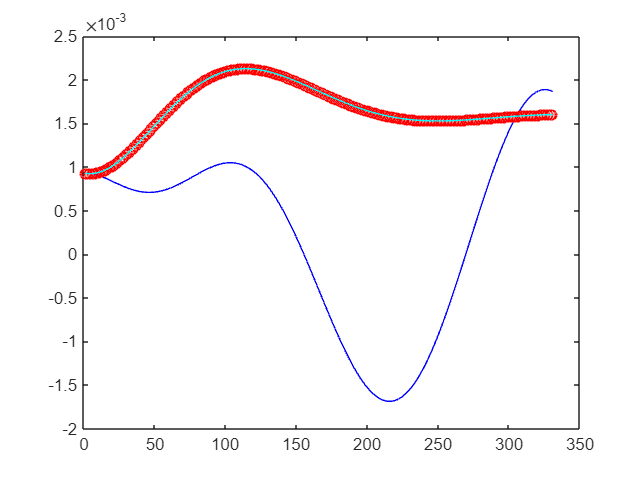

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Atd=A_;
Btd=B_;
Ctd=C;
Atrk=Atilde;
Btrk=Btilde;
Ctrk=C;

xt=zeros(tcdim,N);
yt=zeros(1,N);
ut=zeros(2,N);

epsino=zeros(r,N);
ytrk=zeros(1,N);
utrk=zeros(2,N);

X0=X(1:tcdim,datastart);
xt(:,1)=X0;
epsino(:,1)=pinv(Uuptd)*X0;
for k =1:N
    ut(:,k)=u(:,k);
    xt(:,k+1)=Atd*xt(:,k)+Btd*ut(:,k);
    yt(:,k)=xt(1,k);
    utrk(:,k)=u(:,k);
    epsino(:,k+1)=Atrk*epsino(:,k)+Btrk*ut(:,k);
   
end
xtrkre=Uuptd*epsino;
ytrkre=xtrkre(1,1:datalength);

y=X2(1,:);

figure(40);
plot(timei2,y,'b','DisplayName','origin','Color',[0,0,1]);
hold on;
figure(40);
plot(timei2,yt,'o','DisplayName','DMD','Color',[1,0,0]);
plot(timei2,ytrkre,'b','DisplayName','origin','Color',[0,1,1]);

figure(50)
time2=linspace(1,500,500)

time2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


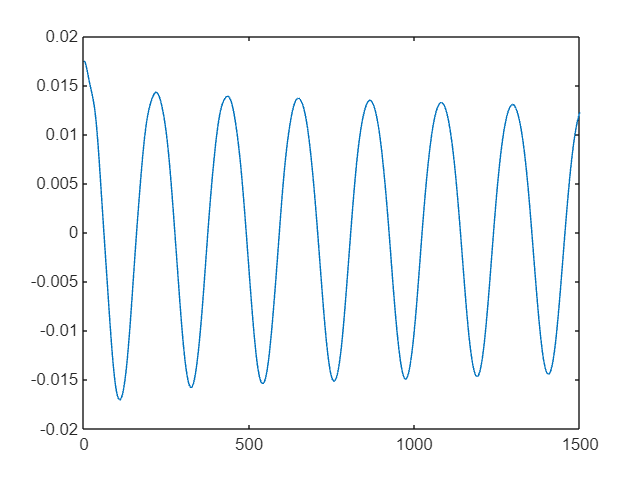

plot(trajs3{1}.zt(1,:))

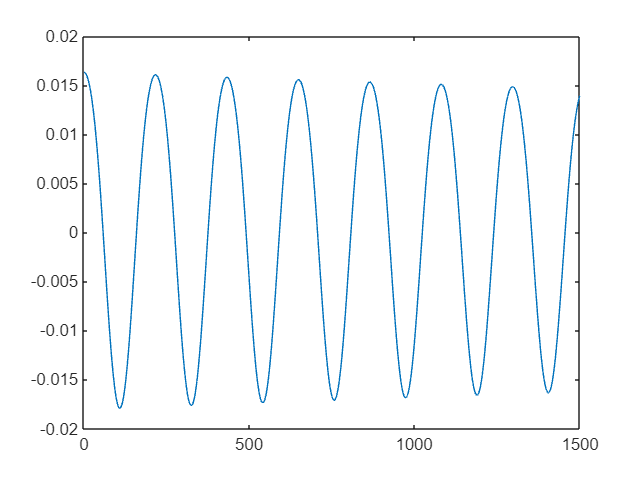

plot(trajs3{1}.zauto(1,:))

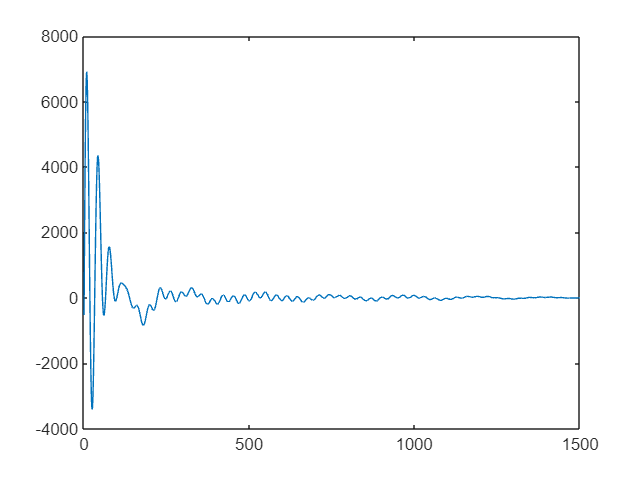

plot(trajs3{1}.ut(1,:))

close all
x0=xtrkre(1:tcdim,1)

x0 = 1.0e-03 *

    0.9288
   -0.0064
    0.0025
    0.8904
   -0.0027
    0.0008
    0.8782
   -0.0029
    0.0007
    0.8757



P=Uuptd;
Nstep=size(ytrkre,2)

Nstep = 330

Atil=Atilde;
Btil=Btilde;
prenewtraj = LQRsc(DS,z0,'nonlinear',tspan,Nstep,auData,W_0,masterModes,cont,P,Atil,Btil,tcdim,datalength,trajs3{1}.zauto,x0)

Call fminunc to find the projection of point on SSM
Time for solving optimization problem is 8.456700e-03 


xout =     0.0169    0.0168    0.0168    0.0168    0.0167    0.0167    0.0166    0.0166    0.0165    0.0164    0.0163    0.0162    0.0161    0.0160    0.0158    0.0157    0.0155    0.0154    0.0152    0.0150    0.0148    0.0146    0.0144    0.0142    0.0140    0.0137    0.0135    0.0132    0.0129    0.0126    0.0123    0.0120    0.0117    0.0114    0.0110    0.0107    0.0103    0.0100    0.0096    0.0092    0.0088    0.0084    0.0080    0.0076    0.0071    0.0067    0.0062    0.0058    0.0053    0.0048
   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001  

prenewtraj = 包含以下字段的 struct :
     time: [0.3000 0.3002 0.3004 0.3006 0.3008 0.3010 0.3012 0.3014 0.3016 0.3018 0.3020 0.3022 0.3024 0.3026 0.3028 0.3030 0.3032 0.3034 0.3036 0.3038 0.3040 0.3042 0.3044 0.3046 0.3048 0.3050 0.3052 0.3054 0.3056 0.3058 0.3060 0.3062 0.3064 0.3066 … ]
       us: [2×330 double]
       xt: [300×330 double]
    xauto: [300×330 double]
     mlus: [2×330 double]
     mlxt: [300×330 double]


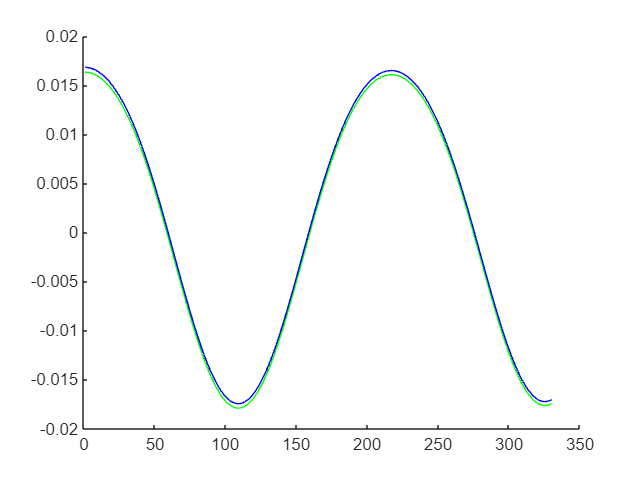

figure(60)
hold on
%plot(prenewtraj.us(1,:),'r')
%plot(0.01*prenewtraj.mlus(1,:),'k')
plot(prenewtraj.xauto(1,:),'g')
plot(prenewtraj.xt(1,:),'b')

%plot(prenewtraj.mlxt(1,:),'y')
%plot(timei2,ytrkre,'b','DisplayName','origin','Color',[0,1,1]);





close all
P=Uuptd;
X0_EP=epsino(:,1);
P_EP=eye(50)

P_EP =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0

pretraj0auto = scLQR0auto(P_EP,Atil,Btil,50,N,X0_EP,cont,0)

xout =    -0.0053   -0.0052   -0.0051   -0.0050   -0.0049   -0.0048   -0.0047   -0.0046   -0.0045   -0.0044   -0.0043   -0.0042   -0.0041   -0.0040   -0.0040   -0.0039   -0.0038   -0.0037   -0.0036   -0.0036   -0.0035   -0.0034   -0.0034   -0.0033   -0.0032   -0.0032   -0.0031   -0.0030   -0.0030   -0.0029   -0.0029   -0.0028   -0.0027   -0.0027   -0.0026   -0.0026   -0.0025   -0.0025   -0.0024   -0.0024   -0.0023   -0.0023   -0.0022   -0.0022   -0.0021   -0.0021   -0.0021   -0.0020   -0.0020   -0.0019
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000  

pretraj0auto = 包含以下字段的 struct :
       us: [2×5000 double]
       xt: [50×5000 double]
    xauto: [50×5000 double]
     mlus: [2×5000 double]
     mlxt: [50×5000 double]


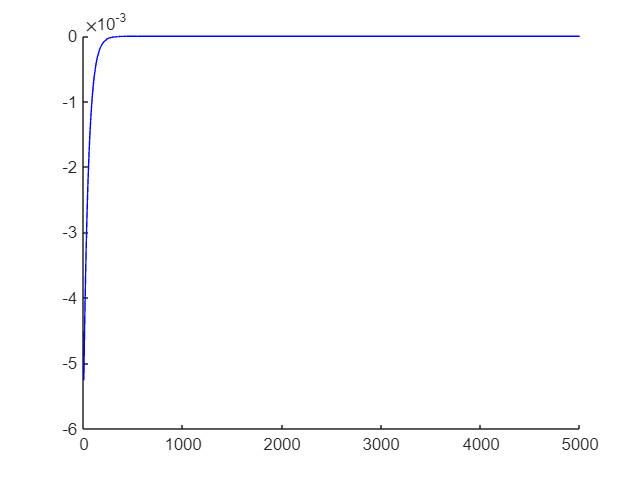


hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
plot(pretraj0auto.xt(1,:),'g')
plot(pretraj0auto.mlxt(1,:),'b')


% plot(pretraj0auto.us(1,:),'g')
% plot(pretraj0auto.mlus(1,:),'b')







ts = [0 0.1 0.2]; nsteps = 499;
nint = numel(ts)-1;
xf = z0;
trajsc = cell(nint,1); tfullsc = cell(nint,1); xfullsc = cell(nint,1);
timefu=traj.time(:,1:499);
% the number of linear modes is very important - to follow
for k=1:nint
    ta = ts(k); tb = ts(k+1);
    tspan = linspace(ta,tb,nsteps);
    
    ufun  = @(t) transpose(interp1(timefu,prenewtraj.us',t,'linear','extrap'));
    set(DS,'u',ufun);
    [tksc, xksc, xkfsc] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
        1, 'nSteps', nsteps,...
        'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',ta);%%%%%%%%%
    % update initial condition
    xf = xkfsc';
    % record results
    trajsc{k}  = traj;
    tfullsc{k} = tksc;
    xfullsc{k} = xksc;
end

错误使用 interp1>reshapeAndSortXandV
LENGTH(X) 和 SIZE(V,1) 必须相同。

出错 interp1 (第 128 行)
    [X,V,orig_size_v] = reshapeAndSortXandV(X,V);

出错 demo_lqr>@(t)transpose(interp1(timefu,prenewtraj.us',t,'linear','extrap')) (<a href="mat

figure; hold on
for k=1:nint
    plot(trajsc{k}.time, trajsc{k}.zt(1,:),'r-');
    plot(tfullsc{k}, xfullsc{k}(:,1),'b-');
end
plot(tfullwo, xfullwo(:,1),'k-');
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w(t)$');
ylabel(zk,'Interpreter','latex');
title('2D Reduction')
set(gca,'FontSize',14);
grid on, axis tight



x = X(:,1:330); 


A = Atd;
B = Btd;
C = zeros(300,300);
C(1,1)=1;
D = zeros(300,2);
K = zeros(2,2);
%x0 = [x1(1);0];
m = idss(A,B,C,D,'Ts',0); % 构建模型 


m.Structure.C.Free = false;
m.Structure.D.Free = false;
m.Structure.K.Free = false;
xlsm=X;


z = iddata(x',u',0.2/500); 

opt = ssestOptions;
% opt.InitialState = idpar(x0); 
opt.InitialState = x0; % initisl state
opt.SearchOption.Tolerance = 1; 
opt.SearchOption.MaxIter = 500;
opt.Display = 'full'; 
% identify
m = ssest(z,m,opt); 


uu = idinput([150,2]);
simdat = iddata([],uu,'Ts',0.1);
simopt = simOptions('InitialCondition', x0);
y = sim(m,simdat,simopt); 
y1 = y.OutputData(:,1);
y2 = y.OutputData(:,2);

figure(1)
subplot(2,1,1)
plot(x1,'r','LineWidth',3)
hold on
plot(y1,'g','LineWidth',3)
hold on
grid on
xlabel('X1')
legend('实际系统','辨识系统')
subplot(2,1,2)
plot(x2,'r','LineWidth',3)
hold on
plot(y2,'g','LineWidth',3)
hold on
grid on
xlabel('X2')
legend('实际系统','辨识系统')
